% Load experiment object
cd /media/ben/'Extreme SSD'/analysisData/conditionV/ % optional 
myFolder =  dir

myFolder = 11×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


subGroups = struct('AvM',[],'AvFW',[],'AvNW',[],'MvFW',[],'MvNW',[],'FWvNW',[])

subGroups = struct with fields:
      AvM: []
     AvFW: []
     AvNW: []
     MvFW: []
     MvNW: []
    FWvNW: []


expStats = struct

expStats = struct with no fields.


numExp = 6

experiments = myFolder(3:2+numExp)

comparGroups = {'AvM','AvFW','AvNW','MvFW','MvNW','FWvNW'};

for ex = 1:length(experiments)
    load(experiments(ex).name)
    vari = experiments(ex).name(1:10)
    [expStats.(vari),subGrp.(vari)] = getComparsion(conditionsStats)
    for grp = 1:length(comparGroups)
        subGroups.(comparGroups{grp}) = [subGroups.(comparGroups{grp});subGrp.(vari).(comparGroups{grp})]
    end
end

stateUnitsUp = find(subGroups.FWvNW(:,3))% == 1 & subGroups.FWvNW(:,1) > 0)
% stateUnitsDown = find(subGroups.FWvNW(:,3) == 1 & subGroups.FWvNW(:,1) < 0)

audUnitsUp = find(subGroups.AvFW(:,3) == 1)% & subGroups.AvFW(:,1) > 0)
% audUnitsDown = find(subGroups.AvFW(:,3) == 1 & subGroups.AvFW(:,1) < 0)

mutedUnitsUp = find(subGroups.FWvNW(:,3) == 1 & subGroups.MvFW(:,1) > 0)
mutedUnitsDown = find(subGroups.FWvNW(:,3) == 1 & subGroups.MvFW(:,1) < 0)

groups =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


unitVec =          0         0         0         0         0         0         0         0         0    5.0000         0    2.5000         0         0         0         0         0    5.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: 0.0028
      tbl: {{4×6 cell}}
    stats: {[1×1 struct]}
        c: {[3×6 double]}
        h: {[3×2 double]}


statStruct = struct with fields:
        p: 0.0028
      tbl: {{4×6 cell}}
    stats: {[1×1 struct]}
        c: {[3×6 double]}
        h: {[3×2 double]}


subGrp = struct with fields:
    AvM: [-110.3366 0.0050]


subGrp = struct with fields:
     AvM: [-110.3366 0.0050 1]
    AvFW: [-102.6750 0.0049]


subGrp = struct with fields:
     AvM: [-110.3366 0.0050 1]
    AvFW: [-102.6750 0.0049 1]
    MvFW: [7.6615 0.9591]


unitVec =          0         0    2.5000    7.5000   10.0000         0         0         0         0    5.0000         0    2.5000         0         0         0         0         0         0         0    2.5000         0         0         0         0         0         0         0    2.5000    2.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19]
      tbl: {{4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19]
      tbl: {{4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [2×3 double]
    AvFW: [-102.6750 0.0049 1]
    MvFW: [7.6615 0.9591 0]


subGrp = struct with fields:
     AvM: [2×3 double]
    AvFW: [2×3 double]
    MvFW: [7.6615 0.9591 0]


subGrp = struct with fields:
     AvM: [2×3 double]
    AvFW: [2×3 double]
    MvFW: [2×3 double]


unitVec =          0         0         0    2.5000    5.0000         0         0         0         0    5.0000         0    2.5000         0         0   10.0000         0         0   15.0000         0         0         0         0         0    5.0000         0         0         0    5.0000         0    5.0000    2.5000         0         0         0         0         0         0         0         0         0    5.0000   10.0000         0         0    2.5000         0         0   10.0000         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [3×3 double]
    AvFW: [2×3 double]
    MvFW: [2×3 double]


subGrp = struct with fields:
     AvM: [3×3 double]
    AvFW: [3×3 double]
    MvFW: [2×3 double]


subGrp = struct with fields:
     AvM: [3×3 double]
    AvFW: [3×3 double]
    MvFW: [3×3 double]


unitVec =     2.5000    5.0000         0         0         0         0         0         0    2.5000         0    2.5000    2.5000         0         0    5.0000         0         0    7.5000         0   12.5000         0         0         0         0         0    5.0000    2.5000         0         0         0   15.0000    7.5000    2.5000   10.0000    5.0000    2.5000         0    5.0000   10.0000   12.5000    7.5000    2.5000    2.5000    2.5000    2.5000    5.0000         0   12.5000    2.5000    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [4×3 double]
    AvFW: [3×3 double]
    MvFW: [3×3 double]


subGrp = struct with fields:
     AvM: [4×3 double]
    AvFW: [4×3 double]
    MvFW: [3×3 double]


subGrp = struct with fields:
     AvM: [4×3 double]
    AvFW: [4×3 double]
    MvFW: [4×3 double]


unitVec =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [5×3 double]
    AvFW: [4×3 double]
    MvFW: [4×3 double]


subGrp = struct with fields:
     AvM: [5×3 double]
    AvFW: [5×3 double]
    MvFW: [4×3 double]


subGrp = struct with fields:
     AvM: [5×3 double]
    AvFW: [5×3 double]
    MvFW: [5×3 double]


unitVec =          0         0         0         0    5.0000         0         0         0         0         0         0         0         0    2.5000   10.0000         0         0         0         0         0         0         0         0         0         0         0    2.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [6×3 double]
    AvFW: [5×3 double]
    MvFW: [5×3 double]


subGrp = struct with fields:
     AvM: [6×3 double]
    AvFW: [6×3 double]
    MvFW: [5×3 double]


subGrp = struct with fields:
     AvM: [6×3 double]
    AvFW: [6×3 double]
    MvFW: [6×3 double]


unitVec =          0         0         0         0    5.0000         0         0         0         0         0         0         0    5.0000         0         0         0    5.0000    2.5000         0    2.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    2.5000    2.5000         0         0         0    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [7×3 double]
    AvFW: [6×3 double]
    MvFW: [6×3 double]


subGrp = struct with fields:
     AvM: [7×3 double]
    AvFW: [7×3 double]
    MvFW: [6×3 double]


subGrp = struct with fields:
     AvM: [7×3 double]
    AvFW: [7×3 double]
    MvFW: [7×3 double]


unitVec =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    2.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    2.5000    2.5000         0         0         0         0         0         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [8×3 double]
    AvFW: [7×3 double]
    MvFW: [7×3 double]


subGrp = struct with fields:
     AvM: [8×3 double]
    AvFW: [8×3 double]
    MvFW: [7×3 double]


subGrp = struct with fields:
     AvM: [8×3 double]
    AvFW: [8×3 double]
    MvFW: [8×3 double]


unitVec =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [9×3 double]
    AvFW: [8×3 double]
    MvFW: [8×3 double]


subGrp = struct with fields:
     AvM: [9×3 double]
    AvFW: [9×3 double]
    MvFW: [8×3 double]


subGrp = struct with fields:
     AvM: [9×3 double]
    AvFW: [9×3 double]
    MvFW: [9×3 double]


unitVec =    12.5000    7.5000    7.5000    7.5000    2.5000         0    2.5000    2.5000    5.0000    5.0000    2.5000    2.5000    5.0000    7.5000    5.0000   10.0000    5.0000    5.0000    2.5000   22.5000   22.5000    7.5000   10.0000   30.0000   12.5000    7.5000   25.0000   10.0000    5.0000   15.0000   30.0000   17.5000   22.5000   30.0000   17.5000   25.0000    7.5000   32.5000   42.5000   52.5000   22.5000   35.0000   27.5000   32.5000   12.5000   15.0000   20.0000   25.0000   27.5000    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [10×3 double]
    AvFW: [9×3 double]
    MvFW: [9×3 double]


subGrp = struct with fields:
     AvM: [10×3 double]
    AvFW: [10×3 double]
    MvFW: [9×3 double]


subGrp = struct with fields:
     AvM: [10×3 double]
    AvFW: [10×3 double]
    MvFW: [10×3 double]


unitVec =     5.0000    2.5000         0         0         0         0         0         0         0         0         0         0         0         0         0    2.5000         0    5.0000   10.0000    2.5000    5.0000    2.5000    5.0000         0         0         0         0    2.5000         0         0         0    5.0000         0    5.0000    2.5000         0   10.0000         0         0    5.0000    2.5000   12.5000    2.5000   15.0000         0   12.5000    7.5000    5.0000    5.0000    5.0000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [11×3 double]
    AvFW: [10×3 double]
    MvFW: [10×3 double]


subGrp = struct with fields:
     AvM: [11×3 double]
    AvFW: [11×3 double]
    MvFW: [10×3 double]


subGrp = struct with fields:
     AvM: [11×3 double]
    AvFW: [11×3 double]
    MvFW: [11×3 double]


unitVec =    15.0000   22.5000         0    5.0000    5.0000         0   12.5000    2.5000    7.5000    5.0000    2.5000         0   17.5000   20.0000   10.0000   20.0000   32.5000   12.5000   25.0000   22.5000   10.0000    5.0000   12.5000    5.0000    7.5000    5.0000    5.0000   17.5000         0   10.0000   12.5000   15.0000   17.5000   17.5000   12.5000   10.0000   12.5000   17.5000   10.0000   15.0000   22.5000   17.5000    5.0000   15.0000   12.5000   15.0000         0   15.0000   12.5000    7.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [12×3 double]
    AvFW: [11×3 double]
    MvFW: [11×3 double]


subGrp = struct with fields:
     AvM: [12×3 double]
    AvFW: [12×3 double]
    MvFW: [11×3 double]


subGrp = struct with fields:
     AvM: [12×3 double]
    AvFW: [12×3 double]
    MvFW: [12×3 double]


unitVec =    10.0000   10.0000   15.0000   17.5000    5.0000   10.0000    7.5000    5.0000   12.5000   12.5000    5.0000   10.0000    7.5000   17.5000   17.5000    7.5000   17.5000   17.5000   17.5000   20.0000   17.5000    7.5000    2.5000   15.0000   22.5000    7.5000    7.5000   20.0000    7.5000   27.5000   17.5000   17.5000   12.5000   15.0000   12.5000    7.5000   10.0000   20.0000   22.5000   25.0000   22.5000   22.5000   20.0000   25.0000   10.0000   15.0000   12.5000    5.0000   17.5000   25.0000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [13×3 double]
    AvFW: [12×3 double]
    MvFW: [12×3 double]


subGrp = struct with fields:
     AvM: [13×3 double]
    AvFW: [13×3 double]
    MvFW: [12×3 double]


subGrp = struct with fields:
     AvM: [13×3 double]
    AvFW: [13×3 double]
    MvFW: [13×3 double]


unitVec =          0         0         0    5.0000    2.5000         0    5.0000         0         0   10.0000         0    2.5000         0    5.0000   10.0000         0         0   30.0000         0    5.0000         0         0         0         0         0         0         0    2.5000         0    5.0000    5.0000         0         0         0         0         0         0         0         0    2.5000         0    7.5000    2.5000    5.0000         0         0         0   12.5000         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]}


subGrp = struct with fields:
     AvM: [14×3 double]
    AvFW: [13×3 double]
    MvFW: [13×3 double]


subGrp = struct with fields:
     AvM: [14×3 double]
    AvFW: [14×3 double]
    MvFW: [13×3 double]


subGrp = struct with fields:
     AvM: [14×3 double]
    AvFW: [14×3 double]
    MvFW: [14×3 double]


unitVec =     7.5000         0         0    5.0000    7.5000         0    2.5000         0         0    7.5000    5.0000    5.0000    7.5000   20.0000   15.0000    2.5000    2.5000    7.5000    2.5000    7.5000    2.5000         0    2.5000    5.0000    5.0000         0         0    2.5000    2.5000   10.0000    2.5000    2.5000    5.0000    2.5000   10.0000    5.0000    5.0000    2.5000    2.5000         0    5.0000    2.5000         0         0         0    2.5000    2.5000    7.5000         0         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×

statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×

subGrp = struct with fields:
     AvM: [15×3 double]
    AvFW: [14×3 double]
    MvFW: [14×3 double]


subGrp = struct with fields:
     AvM: [15×3 double]
    AvFW: [15×3 double]
    MvFW: [14×3 double]


subGrp = struct with fields:
     AvM: [15×3 double]
    AvFW: [15×3 double]
    MvFW: [15×3 double]


unitVec =          0         0         0         0    2.5000         0         0         0         0         0         0    7.5000         0    5.0000    5.0000         0         0   20.0000         0         0         0    2.5000         0    5.0000         0         0         0         0         0    2.5000    2.5000         0         0         0         0    2.5000    2.5000         0    5.0000    5.0000    2.5000   15.0000    2.5000    5.0000         0         0    5.0000   10.0000    5.0000         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 dou

statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 double]  [3×2 dou

subGrp = struct with fields:
     AvM: [16×3 double]
    AvFW: [15×3 double]
    MvFW: [15×3 double]


subGrp = struct with fields:
     AvM: [16×3 double]
    AvFW: [16×3 double]
    MvFW: [15×3 double]


subGrp = struct with fields:
     AvM: [16×3 double]
    AvFW: [16×3 double]
    MvFW: [16×3 double]


unitVec =     2.5000    2.5000   17.5000   22.5000    7.5000    7.5000    7.5000    5.0000    7.5000    2.5000    7.5000   20.0000    5.0000    5.0000    7.5000    5.0000    2.5000    5.0000    5.0000   10.0000    5.0000         0    5.0000   12.5000    5.0000    7.5000    5.0000   12.5000    5.0000    7.5000    5.0000    2.5000         0    2.5000         0    5.0000    2.5000   15.0000    7.5000    7.5000   17.5000   12.5000    5.0000   12.5000    7.5000   10.0000    7.5000    2.5000    2.5000    5.0000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double] 

statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}
        c: {[3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]  [3×6 double]}
        h: {[3×2 double]  [3×2 double]  [3×2 double]  [3×2 double] 

subGrp = struct with fields:
     AvM: [17×3 double]
    AvFW: [16×3 double]
    MvFW: [16×3 double]


subGrp = struct with fields:
     AvM: [17×3 double]
    AvFW: [17×3 double]
    MvFW: [16×3 double]


subGrp = struct with fields:
     AvM: [17×3 double]
    AvFW: [17×3 double]
    MvFW: [17×3 double]


unitVec =          0         0   17.5000   17.5000   10.0000    2.5000   10.0000    5.0000   10.0000    2.5000    7.5000    5.0000    5.0000    7.5000    7.5000    7.5000    5.0000         0         0    2.5000    2.5000    7.5000         0    2.5000    2.5000         0         0         0         0         0         0         0         0         0         0         0         0    2.5000    5.0000    7.5000    5.0000    2.5000         0   15.0000    5.0000    2.5000    7.5000    5.0000    5.0000    5.0000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {1×18 cell}
        c: {1×18 cell}
        h: {1×18 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {1×18 cell}
        c: {1×18 cell}
        h: {1×18 cell}


subGrp = struct with fields:
     AvM: [18×3 double]
    AvFW: [17×3 double]
    MvFW: [17×3 double]


subGrp = struct with fields:
     AvM: [18×3 double]
    AvFW: [18×3 double]
    MvFW: [17×3 double]


subGrp = struct with fields:
     AvM: [18×3 double]
    AvFW: [18×3 double]
    MvFW: [18×3 double]


unitVec =          0         0         0    2.5000    2.5000    2.5000    2.5000         0         0         0    2.5000    2.5000         0         0    5.0000    2.5000    2.5000    2.5000    2.5000         0    2.5000    2.5000         0         0         0         0    2.5000         0         0    2.5000         0         0    2.5000         0    2.5000         0         0         0    2.5000         0         0    2.5000         0         0         0    2.5000         0         0         0    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {1×19 cell}
        c: {1×19 cell}
        h: {1×19 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {1×19 cell}
        c: {1×19 cell}
        h: {1×19 cell}


subGrp = struct with fields:
     AvM: [19×3 double]
    AvFW: [18×3 double]
    MvFW: [18×3 double]


subGrp = struct with fields:
     AvM: [19×3 double]
    AvFW: [19×3 double]
    MvFW: [18×3 double]


subGrp = struct with fields:
     AvM: [19×3 double]
    AvFW: [19×3 double]
    MvFW: [19×3 double]


unitVec =     2.5000    2.5000   15.0000   35.0000   27.5000   12.5000   10.0000    5.0000    5.0000         0   10.0000    2.5000         0    2.5000   10.0000    5.0000   10.0000         0         0    5.0000    2.5000    5.0000         0    7.5000   12.5000         0   25.0000    7.5000    2.5000   17.5000   17.5000         0   12.5000   17.5000   17.5000    5.0000         0   17.5000   20.0000   35.0000   37.5000   27.5000   12.5000   35.0000   17.5000   22.5000   10.0000    7.5000    5.0000    5.0000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {1×20 cell}
        c: {1×20 cell}
        h: {1×20 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10]
      tbl: {{4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}  {4×6 cell}}
    stats: {1×20 cell}
        c: {1×20 cell}
        h: {1×20 cell}


subGrp = struct with fields:
     AvM: [20×3 double]
    AvFW: [19×3 double]
    MvFW: [19×3 double]


subGrp = struct with fields:
     AvM: [20×3 double]
    AvFW: [20×3 double]
    MvFW: [19×3 double]


subGrp = struct with fields:
     AvM: [20×3 double]
    AvFW: [20×3 double]
    MvFW: [20×3 double]


unitVec =          0    2.5000         0         0         0         0         0         0         0         0         0    2.5000    5.0000    2.5000    7.5000         0    2.5000    5.0000    5.0000    7.5000    2.5000    5.0000    7.5000    5.0000         0         0    2.5000    2.5000         0         0         0         0         0    2.5000         0         0    5.0000    2.5000    5.0000   10.0000    5.0000   22.5000    7.5000    7.5000    5.0000    5.0000   12.5000   10.0000    2.5000    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47]
      tbl: {1×21 cell}
    stats: {1×21 cell}
        c: {1×21 cell}
        h: {1×21 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47]
      tbl: {1×21 cell}
    stats: {1×21 cell}
        c: {1×21 cell}
        h: {1×21 cell}


subGrp = struct with fields:
     AvM: [21×3 double]
    AvFW: [20×3 double]
    MvFW: [20×3 double]


subGrp = struct with fields:
     AvM: [21×3 double]
    AvFW: [21×3 double]
    MvFW: [20×3 double]


subGrp = struct with fields:
     AvM: [21×3 double]
    AvFW: [21×3 double]
    MvFW: [21×3 double]


unitVec =     5.0000         0    2.5000         0    7.5000    7.5000    5.0000    5.0000         0         0    2.5000    7.5000    2.5000   20.0000   12.5000    5.0000    2.5000    7.5000    2.5000   10.0000         0    5.0000    5.0000    5.0000         0    7.5000         0    2.5000         0    5.0000         0    2.5000    2.5000    2.5000    2.5000    2.5000         0    7.5000    2.5000    7.5000    2.5000    5.0000    2.5000    2.5000    5.0000    5.0000         0    2.5000    7.5000         0


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47 6.3714e-13]
      tbl: {1×22 cell}
    stats: {1×22 cell}
        c: {1×22 cell}
        h: {1×22 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47 6.3714e-13]
      tbl: {1×22 cell}
    stats: {1×22 cell}
        c: {1×22 cell}
        h: {1×22 cell}


subGrp = struct with fields:
     AvM: [22×3 double]
    AvFW: [21×3 double]
    MvFW: [21×3 double]


subGrp = struct with fields:
     AvM: [22×3 double]
    AvFW: [22×3 double]
    MvFW: [21×3 double]


subGrp = struct with fields:
     AvM: [22×3 double]
    AvFW: [22×3 double]
    MvFW: [22×3 double]


unitVec =     7.5000    2.5000    7.5000    7.5000    2.5000    2.5000    7.5000    5.0000    5.0000    7.5000    7.5000   10.0000    2.5000   12.5000    2.5000    5.0000    7.5000    2.5000    2.5000   12.5000   15.0000         0    2.5000    2.5000    2.5000         0    5.0000    2.5000    7.5000   15.0000   10.0000    7.5000   12.5000    2.5000         0         0   10.0000   10.0000   15.0000   10.0000   15.0000    5.0000   12.5000   10.0000    2.5000   10.0000         0    5.0000   25.0000    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47 6.3714e-13 0.0575]
      tbl: {1×23 cell}
    stats: {1×23 cell}
        c: {1×23 cell}
        h: {1×23 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47 6.3714e-13 0.0575]
      tbl: {1×23 cell}
    stats: {1×23 cell}
        c: {1×23 cell}
        h: {1×23 cell}


subGrp = struct with fields:
     AvM: [23×3 double]
    AvFW: [22×3 double]
    MvFW: [22×3 double]


subGrp = struct with fields:
     AvM: [23×3 double]
    AvFW: [23×3 double]
    MvFW: [22×3 double]


subGrp = struct with fields:
     AvM: [23×3 double]
    AvFW: [23×3 double]
    MvFW: [23×3 double]


unitVec =     5.0000    2.5000    2.5000         0         0         0         0         0         0         0         0    5.0000    7.5000    5.0000    2.5000    2.5000         0    2.5000         0         0         0    2.5000         0         0         0         0         0         0         0         0         0         0    2.5000         0         0         0         0         0         0         0         0    2.5000         0    2.5000         0         0         0         0         0    2.5000


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


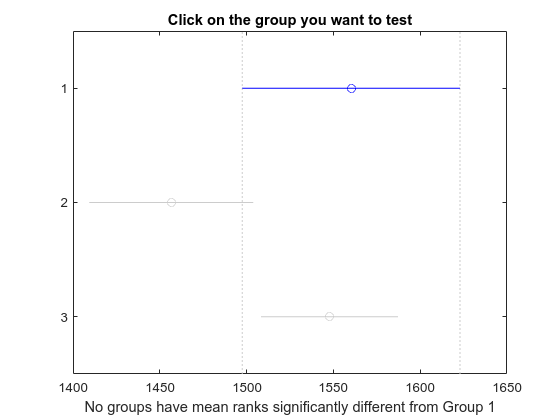

statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47 6.3714e-13 0.0575 0.0102]
      tbl: {1×24 cell}
    stats: {1×24 cell}
        c: {1×24 cell}
        h: {1×24 cell}


statStruct = struct with fields:
        p: [0.0028 4.9854e-19 4.4887e-09 0.0287 4.8779e-15 0.4395 2.2150e-08 0.0048 2.7148e-69 8.2025e-12 2.5582e-21 1.6070e-16 2.2792e-04 2.3908e-07 1.1891e-24 4.6277e-19 8.3679e-20 2.1689e-50 1.1283e-31 4.2857e-10 2.7505e-47 6.3714e-13 0.0575 0.0102]
      tbl: {1×24 cell}
    stats: {1×24 cell}
        c: {1×24 cell}
        h: {1×24 cell}


subGrp = struct with fields:
     AvM: [24×3 double]
    AvFW: [23×3 double]
    MvFW: [23×3 double]


subGrp = struct with fields:
     AvM: [24×3 double]
    AvFW: [24×3 double]
    MvFW: [23×3 double]


subGrp = struct with fields:
     AvM: [24×3 double]
    AvFW: [24×3 double]
    MvFW: [24×3 double]


Unrecognized property 'stat' for class 'auditory_ephys_exp'.

[FVB103_757.stat,FVB103_757.grp] = getComparsion(conditionsStats)

h = vennEulerDiagram({stateUnitsUp,stateUnitsDown,audUnitsUp,audUnitsDown,mutedUnitsUp,mutedUnitsDown} , 'drawProportional', true,'SetLabels', ["A"; "B"; "C";"D";"E";"F"]);

function [statStruct,subGrp] = getComparsion(conditionsStats)

groups = [ones(size(conditionsStats.binned.aluminum,2),1);ones(size(conditionsStats.binned.muted,2) ...
    ,1)*2;ones(size(conditionsStats.binned.non,2),1)*3]%;ones(size(conditionsStats.binned.noWhisk,2),1)*4]

% comparGroups = {'AvM','AvFW','AvNW','MvFW','MvNW','FWvNW'};
comparGroups = {'AvM','AvFW','MvFW'};

for unitNum = 1:size(conditionsStats.binned.aluminum,1)
    unitVec = [conditionsStats.binned.aluminum(unitNum,:),conditionsStats.binned.muted(unitNum,:),conditionsStats.binned.non(unitNum,:)]%,conditionsStats.binned.noWhisk(unitNum,:)]
    [statStruct.p(unitNum),statStruct.tbl{unitNum},statStruct.stats{unitNum}] = kruskalwallis(unitVec,groups,'off');

    [statStruct.c{unitNum},statStruct.h{unitNum}] = multcompare(statStruct.stats{unitNum},'Alpha',0.025)%,"Display","off")
    
    for grp = 1:3
        subGrp.(comparGroups{grp})(unitNum,1:2) = statStruct.c{unitNum}(grp,[4,6])
        if subGrp.(comparGroups{grp})(unitNum,2) < 0.025
            subGrp.(comparGroups{grp})(unitNum,3) = 1;
        else
            subGrp.(comparGroups{grp})(unitNum,3) = 0;
        end
    end

end
end


